# Parcial 2 Control y Sistemas

**Nombre y apellido alumno: **

## Objetivos

Proponer una solución a la siguiente problemática utilizando conceptos de la materia y el criterio de ingeniería construido en las clases. 

Guardar este template en su directorio de trabajo con el siguiente nombre (colocando su nombre). Lo mismo para el enunciado de simulink/simscape.

`parcial2_livescript_NOMBRE_APELLIDO.mlx   (live script)`

`parcial2_planta_NOMBRE_APELLIDO.slx   (simulink/simscape)`

Una vez finalizado el examen enviar los 5 archivos: 1 live script + 4 archivos de simulink que se realizarán a medida que avance en el examen a las siguiente dirección de correo:

`carloshernangarrido@gmail.com`

    `CC: `

    `mauricio.caceres@ingenieria.uncuyo.edu.ar`

## Sección 1: Diseño y validación de planta

Construya un modelo en simulink usando simscape (mecánica traslacional) de la suspensión de un cuarto de vehículo (un colectivo).Los parámetros se dan abajo.Las perturbaciones del terreno aparecen a los 50 segundos y se modelan como un ruido de `1 m/s^2 RMS` (el bloque Band-Limited White Noise ya está configurado). SI EL MODELO ES CORRECTO, generan compresiones de la suspensión de 3 a 4 cm pico.

Guarde la solución en un archivo con nombre:  "`parcial2_planta_NOMBRE_APELLIDO.slx"`

%% Parameters (golden car)
%clc
%clear
close all

m_s = 3000;  % Sprung mass (masa del chasis por rueda) (kg)
k_s = 63.3*m_s;  % Spring stiffness (rigidez del resorte) (N/m)
c_s = 6*m_s;  % Damping coefficient (coeficiente de amortiguamiento del amortiguador) (Ns/m)
k_t = 653*m_s;  % Tire stiffness (rigidez del neumático) (N/m)
c_t = 0;  % Tire damping (Ns/m)
m_u = 0.15*m_s;  % (masa de la rueda) Unsprung mass (kg)

## Sección 2: Diseño de control PID

- Haga una copia del modelo de simulink/simscape. Coloque como nombre

`parcial2_PID_NOMBRE_APELLIDO.slx `

Considerando un sensor ideal de distancia para medir la compresión de la suspensión: Implemente un PID para que el colectivo descienda y permita el ingreso de pasajeros. 

Este controlador, cuando el chofer da un escalón a la referencia de -15 cm a los 10 s, debe hacer que la suspensión se comprima 15 cm,  sin error en estado estacionario, sin sobre-impulso y con un tiempo de establecimiento de menos de 1.0 s.

Por otra parte, cuando sube el pasajero, modelado como perturbación tipo escalón de 700 N a los 20 s, el controlador debe rechazar la perturbación con un tiempo de establecimiento de menos de 1.0 s.

Para esto puede usar el comando 

%pidTuner(H, 'PID');

y obtener las ganancias por tanteo observando la tabla mostrada al pulsar el botón` Show Parameters.`Completar  los valores faltantes en las matrices a continuación para poder ejecutar el script

%% Diseño del PID
% x = [pos_u
%      pos_s
%      vel_u
%      vel_s]

M = [m_u 0
     0   m_s];
K = [k_s+k_t -k_s
     -k_s     k_s]

K =      2148900     -189900
     -189900      189900


C = [c_s+c_t -c_s
     -c_s     c_s]

C =        18000      -18000
      -18000       18000


A_ss = [ 0 0 1 0 
         0 0 0 1
        -M\K -M\C] 

A_ss = 1.0e+03 *

         0         0    0.0010         0
         0         0         0    0.0010
   -4.7753    0.4220   -0.0400    0.0400
    0.0633   -0.0633    0.0060   -0.0060


B_ss = [ 0
         0
         (M^-1) * [ -1
                    1 ]]    

B_ss =          0
         0
   -0.0022
    0.0003


Elijo esos valores porque la accion de control es aplicada entre las dos masas, es relativa. Como M está invertida entonces la ecuacion es $-m_s + m_u$

C_ss = [ 1 -1 0 0] 

C_ss =      1    -1     0     0


En el caso de C_ss no hay inversion de las variables de estado, así que es $m_u - m_s$

D_ss = [ 0 ]

D_ss = 0

     
H = tf(ss(A_ss, B_ss, C_ss, D_ss))

H =
 
        -0.002556 s^2 - 1.208e-33 s - 1.451
  -----------------------------------------------
  s^4 + 46 s^3 + 4839 s^2 + 2.612e04 s + 2.756e05
 
Continuous-time transfer function.
Model Properties


stepinfo(H)

ans = struct with fields:
         RiseTime: 0.2246
    TransientTime: 1.4353
     SettlingTime: 1.4353
      SettlingMin: -6.8378e-06
      SettlingMax: -4.7432e-06
        Overshoot: 29.8492
       Undershoot: 0
             Peak: 6.8378e-06
         PeakTime: 0.4468


%pidTuner(H, 'PID');

Kp = controladorPID.Kp *0.71

Kp = -1.8228e+05

Ki = controladorPID.Ki *0.91

Ki = -9.6735e+05

Kd = controladorPID.Kd *1

Kd = -1.5501e+04

Gc  = tf([Kd Kp Ki], [1 0]);  % Para poder medir adecuadamente el overshoot y el settling time, voy a armar la funcion de trasnferencia a lazo cerrado
Hlc = H*Gc/(1+H*Gc);
stepinfo(Hlc)

ans = struct with fields:
         RiseTime: 0.2785
    TransientTime: 0.8903
     SettlingTime: 0.8903
      SettlingMin: 0.8493
      SettlingMax: 0.9998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9998
         PeakTime: 1.6770


Logrando ajustar manualmente las ganacias Kp, Ki y Kd, logramos que frente al escalon unitario el sistema tenga una respuesta temporal adecuada, con Settling Time de $0.8903 s$ y $0$% de Overshoot. Los valores se copiaron numéricamente al PID en el archivo .slx

En caso que se borre o se pierdan los valores, dejo una captura:

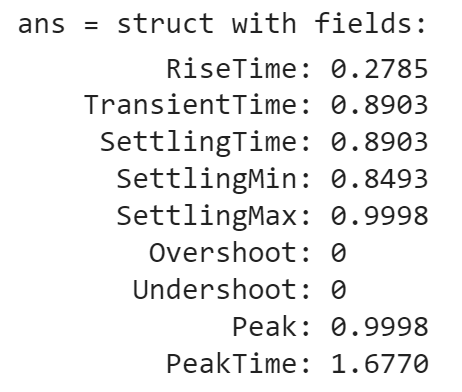


$$Kd = -1.550062364876860e+04$$



$$Kp = -1.822778704265652e+05$$



$$Ki = -9.673495273087375e+05$$


## Sección 3: Limitación de la acción de control del sistema

- Haga una copia del modelo de simulink/simscape. Coloque como nombre

`parcial2_PID_avanzado_NOMBRE_APELLIDO.slx`

Modifique el controlador de manera que la acción de control nunca supere los 40000 N en valor absoluto. Tendrá que agregar algún/algunos bloque/bloques. Se permite degradación del desempeño ante el escalón en la referencia, pero ante el escalón de la perturbación debe mantener la dinámica

La mejor forma de evitar valores elevados en la acción de control es eliminando de la rama principal las acciones P y D, ya que frente al escalón generan grandes valores de control. La solución es utilizar un controlador de tipo I-PD, donde solo se corriga el error de estado estacionario en la rama directa con integrador y en la retroalimentacion se usa acción proporcional y derivativa con la salida. Los valores de Kp, Ki y Kd serán los mismos, y el esfuerzo de control frente a escalones en la referencia debería disminuir.

## Sección 4: Control LQR

- Haga una copia del modelo de simulink/simscape de la sección 1

- Elimine el bloque PID, pero mantenga el modelo de la planta en simscape. Coloque el nombre

`parcial2_LQR_NOMBRE_APELLIDO.slx `

Agregue un controlador LQR ($K$), con seguimiento de referencia por feedforward ($k_r$), y acción integral ($k_i$). LAs matrices de ganancias $K$, $k_i$ y $k_r$ deben estar explícitas en el diagrama en bloques. 

No es necesario diseñar los valores óptimos para $K$, $k_i$ y $k_r$ (puede asignar valores 1 a todos los elementos como prueba), pero el modelo debe poder ejecutarse. Es decir, las dimensiones de las matrices deben ser consistentes para que simulink no de error.

A_aug = [A_ss zeros(4,1)
         C_ss      0]

A_aug = 1.0e+03 *

         0         0    0.0010         0         0
         0         0         0    0.0010         0
   -4.7753    0.4220   -0.0400    0.0400         0
    0.0633   -0.0633    0.0060   -0.0060         0
    0.0010   -0.0010         0         0         0


B_aug = [B_ss
        0]

B_aug =          0
         0
   -0.0022
    0.0003
         0


C_aug = [C_ss 0]

C_aug =      1    -1     0     0     0


D_aug = [D_ss
        0]

D_aug =      0
     0


Qx = eye(5,5)

Qx =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


R = 1

R = 1


K_aug = lqr(A_aug, B_aug, Qx, R)

K_aug =    -0.0951    0.0948   -0.0000    0.0158   -1.0000


K = K_aug(1:4)

K =    -0.0951    0.0948   -0.0000    0.0158


Ki = K_aug(5)

Ki = -1.0000

kr = -inv(C_ss*inv(A_ss -B_ss*K)*B_ss)

kr = -1.8990e+05